# Análisis de borde y asimetría

#### Lista de parámetros

- originalImage: imagen por manipular (debe estar en el modelo RGB)

- order: orden del filtro Butterworth paso bajas

- cf: Frecuencia de corte del filtro paso bajas

- maxClusters: Número de clusters

- maxIter: número máximo de iteraciones para el algoritmo de segmentación

Las imagenes incluidas en el reporte son: 399, 402, 3 y 1185

originalImage = imread('malignant/399.jpg');
order = 10;        
cf = 20;           
maxClusters = 15;  
maxIter = 100;     

#### Propuesta con Poca Aportación

- Imagen original

- Imagen en blanco y negro

- Imagen binaria de la imagen en blanco y negro

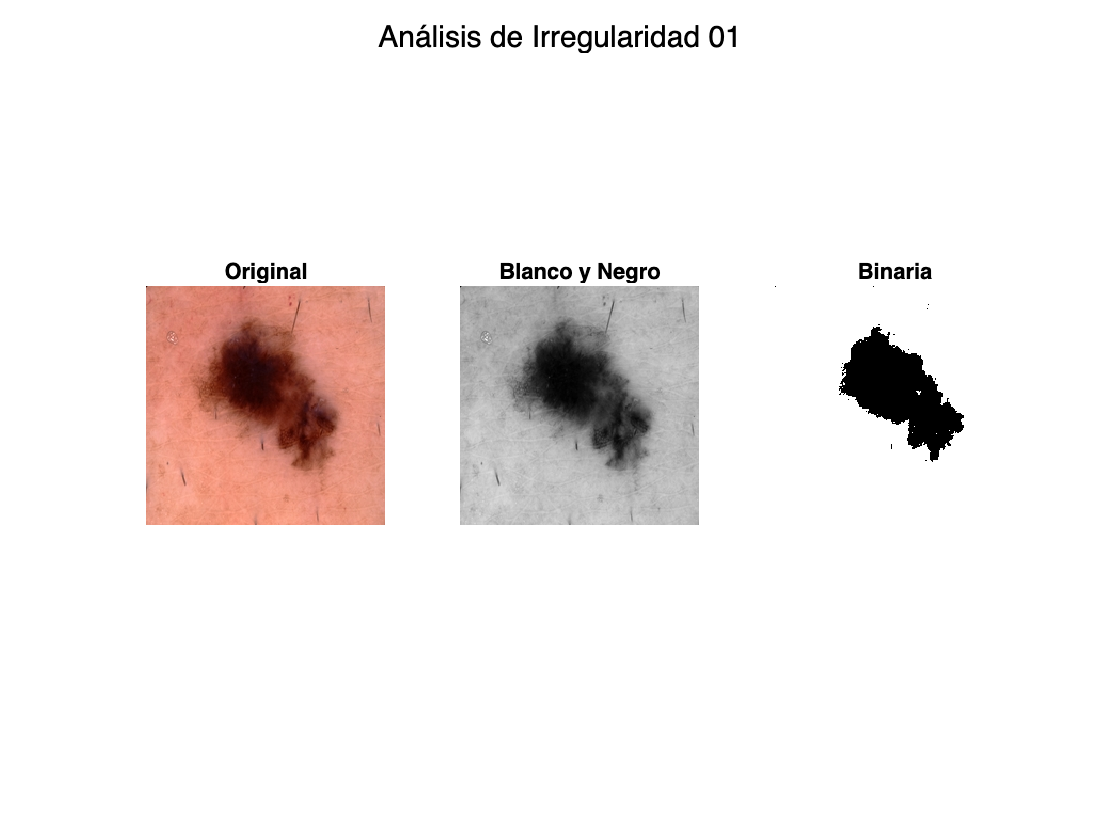

results01 = cell(1, 3);
results01{1,1} = originalImage;
results01{1,2} = im2gray(originalImage);
results01{1,3} = modifyIntensity(originalImage,2);
showMultipleImages('Análisis de Irregularidad 01', results01 ,{'Original','Blanco y Negro','Binaria'});

#### Resultado óptimo: indicando el número de clústers

- Imagen original

- Imagen segmentada

- Imagen en blanco y negro de la imagen segmentada

- Imagen binaria de la imagen blanco y negro

- Imagen con filtro paso bajas butterworth de la imagen blanco y negro

- Imagen binaria de la imagen con filtro paso bajas butterworth

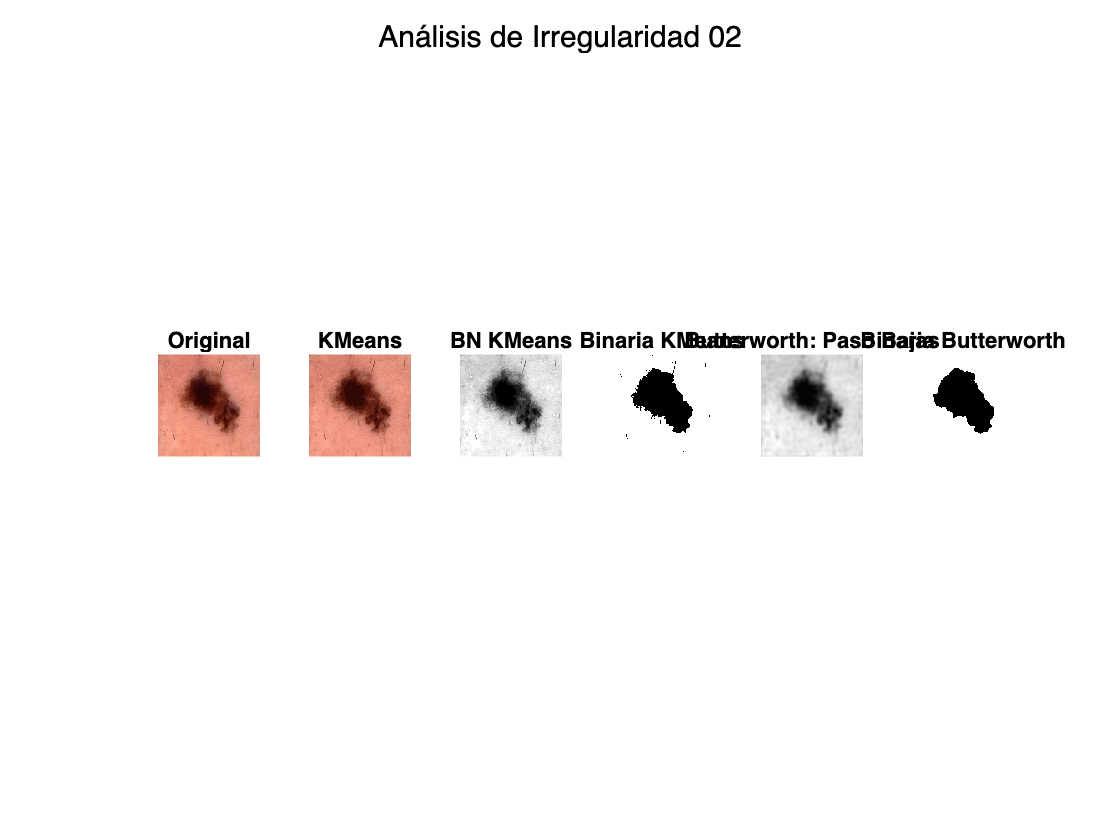

results02 = cell(1, 6);
results02{1,1} = originalImage;
results02{1,2} = kMeans(originalImage,maxClusters,maxIter);
results02{1,3} = im2uint8(im2gray(results02{1,2}));
results02{1,4} = modifyIntensity(results02{1,3},2);
results02{1,5} = butterworth(results02{1,3} , order, cf);
results02{1,6} = modifyIntensity(uint8(results02{1,5}),2);
showMultipleImages('Análisis de Irregularidad 02',results02,{'Original','KMeans','BN KMeans','Binaria KMeans','Butterworth: Paso Bajas','Binaria Butterworth'});

#### Resultado óptimo: sin indicar el número de clústers

- Imagen original

- Imagen segmentada

- Imagen en blanco y negro de la imagen segmentada

- Imagen binaria de la imagen blanco y negro

- Imagen con filtro paso bajas butterworth de la imagen blanco y negro

- Imagen binaria de la imagen con filtro paso bajas butterworth

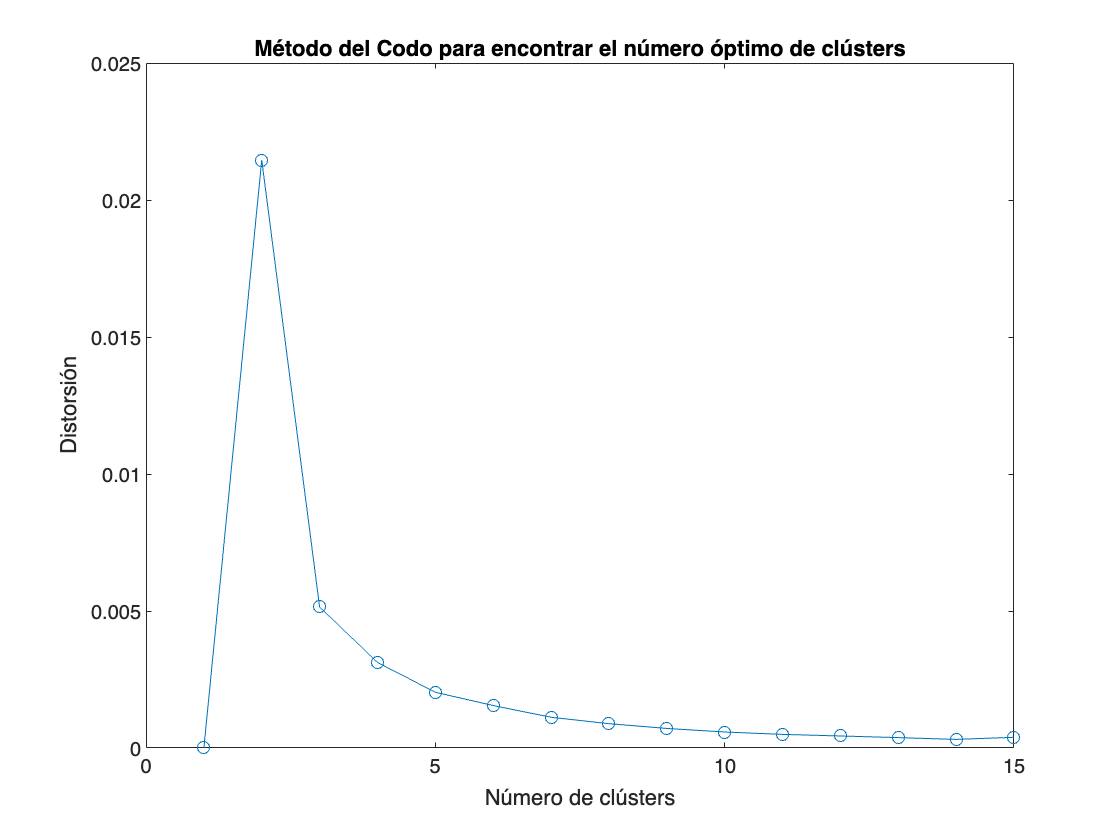

         0    0.0215    0.0051    0.0031    0.0020    0.0015    0.0011    0.0009    0.0007    0.0006    0.0005    0.0004    0.0004    0.0003    0.0004

El número óptimo de clústers es: 5.146583e-03
     5



optimalCluster = floor(findOptimalCluster(originalImage, maxClusters, maxIter));

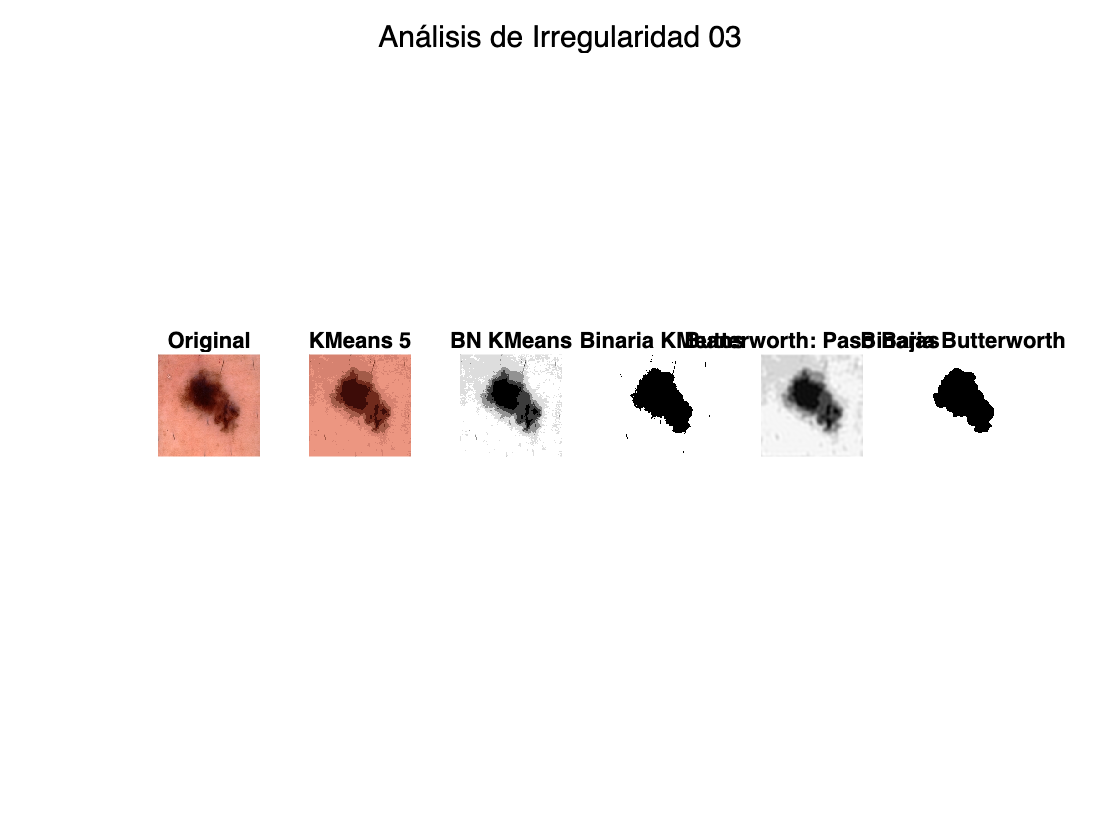

results03 = cell(1, 6);
results03{1,1} = originalImage;
results03{1,2} = kMeans(originalImage,optimalCluster,maxIter);
results03{1,3} = im2uint8(im2gray(results03{1,2}));
results03{1,4} = modifyIntensity(results03{1,3},2);
results03{1,5} = butterworth(results03{1,3} , order, cf);
results03{1,6} = modifyIntensity(uint8(results03{1,5}),2);
showMultipleImages('Análisis de Irregularidad 03',results03,{'Original',['KMeans ', num2str(optimalCluster)], 'BN KMeans','Binaria KMeans','Butterworth: Paso Bajas','Binaria Butterworth'});

#### Resultado óptimo en HSI: indicando el número de clusters

- Imagen en el modelo HSI

- Imagen segmentada

- Imagen en blanco y negro de la imagen segmentada

- Imagen en blanco y negro de la imagen segmentada (ecualizada)

- Imagen binaria de la imagen blanco y negro ecualizada

- Imagen con filtro paso bajas butterworth de la imagen blanco y negro

- Imagen binaria de la imagen con filtro paso bajas butterworth

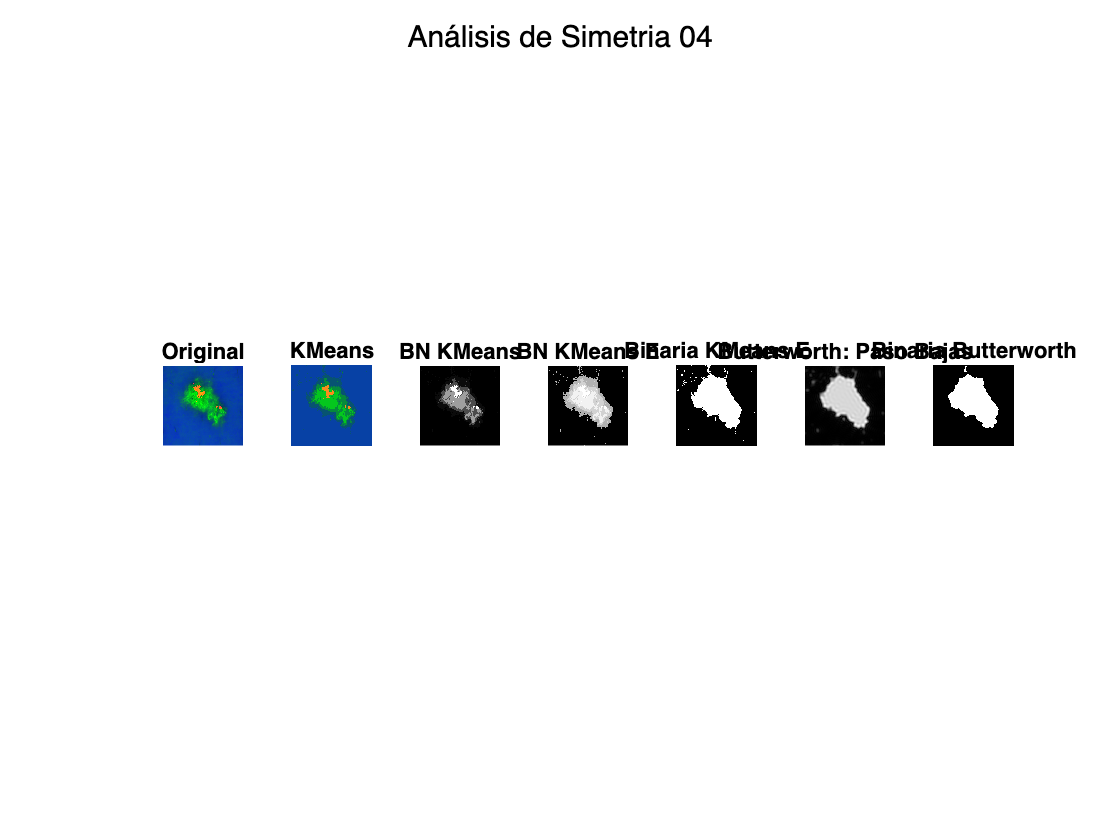

HSIImage = rgbTohsi(originalImage);
KHSIImage = kMeans(HSIImage,8,500);
results04 = cell(1, 6);
results04{1,1} = HSIImage;
results04{1,2} = kMeans(HSIImage,5,500)*255;
results04{1,3} = im2gray(results04{1,2});
results04{1,4} = histeq((im2gray(results04{1,2})));
results04{1,5} = modifyIntensity(uint8(results04{1,4}*255),2);
results04{1,6} = butterworth(results04{1,5} , order, cf);
results04{1,7} = modifyIntensity(uint8(results04{1,6}),2);
showMultipleImages('Análisis de Simetria 04',results04,{'Original','KMeans','BN KMeans','BN KMeans E','Binaria KMeans E','Butterworth: Paso Bajas','Binaria Butterworth'});